load("modelo_lin.mat")

latmod

latmod =
 
  A = 
                 v           p           r         phi         psi
   v        -0.875      0.8751      -16.82       9.791           0
   p        -2.831      -16.14       3.377           0           0
   r         1.706      0.5154      -2.783           0           0
   phi           0           1     0.05385  -1.455e-24           0
   psi           0           0       1.001  -2.706e-23           0
 
  B = 
        aileron   rudder
   v          0    5.317
   p     -156.9   -5.022
   r      11.54   -82.27
   phi        0        0
   psi        0        0
 
  C = 
               v        p        r      phi      psi
   beta  0.05882        0        0        0        0
   p           0        1        0        0        0
   r           0        0        1        0        0
   phi         0        0        0        1        0
   psi         0        0        0        0        1
 
  D = 
         aileron   rudder
   beta        0        0
   p           0        0
   r   

latmod.A(4,4) = 0;
latmod.A(5,4) = 0;

Funciones de transferencia

TransferFunctions = tf(latmod);

Función


$$\frac{p}{\textrm{aileron}}$$


G1 = TransferFunctions(2,1)

G1 =
 
  From input "aileron" to output "p":
     -156.9 s^3 - 535 s^2 - 4302 s + 123.9
  -------------------------------------------
  s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
Continuous-time transfer function.



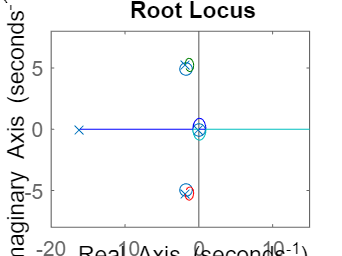

rlocus(G1)

kd1 = 0.106;
Go1 = feedback(kd1*G1,1)

Go1 =
 
  From input "aileron" to output:
     -16.63 s^3 - 56.71 s^2 - 456 s + 13.14
  ---------------------------------------------
  s^4 + 3.164 s^3 + 34.19 s^2 + 49.08 s + 20.12
 
Continuous-time transfer function.



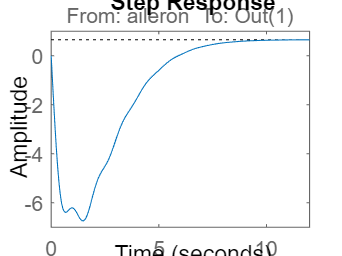

step(Go1)

stepinfo(Go1)

ans = struct with fields:
         RiseTime: 2.731525995919078
    TransientTime: 7.820725293680410
     SettlingTime: 10.537241798601622
      SettlingMin: 0.588564408917788
      SettlingMax: 0.649896934921063
        Overshoot: 0
       Undershoot: 1.031711902305885e+03
             Peak: 6.737910361921394
         PeakTime: 1.488367545690583


Función


$$\frac{r}{\textrm{rudder}}$$


G2 = TransferFunctions(3,2)

G2 =
 
  From input "rudder" to output "r":
     -82.27 s^3 - 1393 s^2 - 1237 s - 2365
  -------------------------------------------
  s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
Continuous-time transfer function.



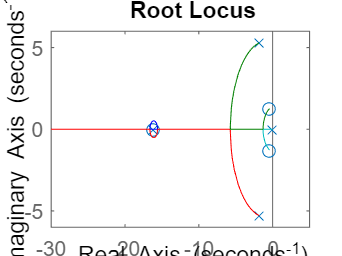

rlocus(-G2)

kd2 = -0.2;
Go2 = feedback(kd2*G2,1)

Go2 =
 
  From input "rudder" to output:
     16.45 s^3 + 278.6 s^2 + 247.3 s + 472.9
  ---------------------------------------------
  s^4 + 36.25 s^3 + 369.6 s^2 + 752.4 s + 479.9
 
Continuous-time transfer function.



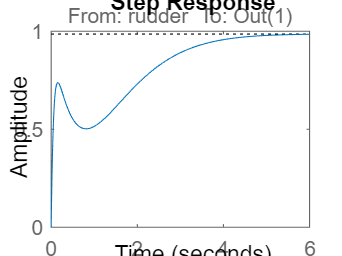

step(Go2)

stepinfo(Go2)

ans = struct with fields:
         RiseTime: 2.961112645456907
    TransientTime: 4.276055626761272
     SettlingTime: 4.276055626761272
      SettlingMin: 0.887356383504396
      SettlingMax: 0.985398364611102
        Overshoot: 0
       Undershoot: 0
             Peak: 0.985398364611102
         PeakTime: 6.937318757409544


Retroalimentación

kd = [kd1 0;0 kd2]

kd =    0.106000000000000                   0
                   0  -0.200000000000000


feedin = [1 2]

feedin =      1     2


feedout = [2 3]

feedout =      2     3


CASLatMod = feedback(latmod*kd,eye(2),feedin,feedout)

CASLatMod =
 
  A = 
              v        p        r      phi      psi
   v     -0.875   0.8751   -15.76    9.791        0
   p     -2.831   0.4939    2.372        0        0
   r      1.706  -0.7074   -19.24        0        0
   phi        0        1  0.05385        0        0
   psi        0        0    1.001        0        0
 
  B = 
            u1      u2
   v         0  -1.063
   p    -16.63   1.004
   r     1.223   16.45
   phi       0       0
   psi       0       0
 
  C = 
               v        p        r      phi      psi
   beta  0.05882        0        0        0        0
   p           0        1        0        0        0
   r           0        0        1        0        0
   phi         0        0        0        1        0
   psi         0        0        0        0        1
 
  D = 
         u1  u2
   beta   0   0
   p      0   0
   r      0   0
   phi    0   0
   psi    0   0
 
Continuous-time state-space model.



Funciones de transferencia

CASTransferFunctions = tf(CASLatMod);

Función


$$\frac{\phi }{\textrm{aileron}}$$


G11 = CASTransferFunctions(4,1)

G11 =
 
  From input to output "phi":
          -16.57 s^2 - 331 s - 670.7
  -------------------------------------------
  s^4 + 19.62 s^3 + 37.94 s^2 + 82.38 s + 493
 
Continuous-time transfer function.



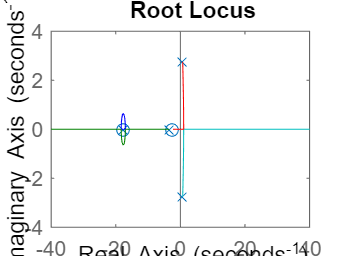

rlocus(G11)

kp1 = -0.12;
Go11 = feedback(kp1*G11,1)

Go11 =
 
           1.988 s^2 + 39.71 s + 80.48
  ---------------------------------------------
  s^4 + 19.62 s^3 + 39.93 s^2 + 122.1 s + 573.5
 
Continuous-time transfer function.



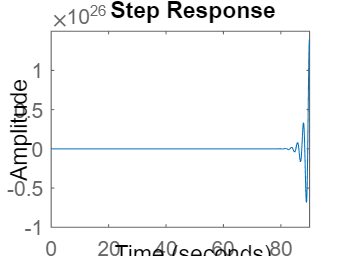

step(Go11)

stepinfo(Go11)

ans = struct with fields:
         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: NaN
       Undershoot: NaN
             Peak: Inf
         PeakTime: Inf


Función


$$\frac{\psi \;}{\textrm{rudder}}$$


G22 = CASTransferFunctions(5,2)

G22 =
 
  From input to output "psi":
      16.48 s^3 + 3.751 s^2 + 33.35 s + 473.6
  -----------------------------------------------
  s^5 + 19.62 s^4 + 37.94 s^3 + 82.38 s^2 + 493 s
 
Continuous-time transfer function.



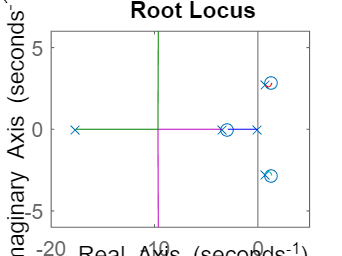

rlocus(G22)

kp2 = 0.15;
Go22 = feedback(kp2*G22,1)

Go22 =
 
         2.472 s^3 + 0.5626 s^2 + 5.003 s + 71.04
  -------------------------------------------------------
  s^5 + 19.62 s^4 + 40.41 s^3 + 82.94 s^2 + 498 s + 71.04
 
Continuous-time transfer function.



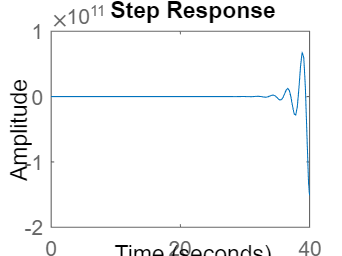

step(Go22)

stepinfo(Go22)

ans = struct with fields:
         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: NaN
       Undershoot: NaN
             Peak: Inf
         PeakTime: Inf
